G(jw)

syms w G0(s) real

k=2

k = 2

G0(s)=k/(s+1)/(s-0.5);
jw=1i*w;
A=abs(G0(jw))

$$A = \frac{2}{\sqrt{w^{2}+1}\,\sqrt{w^{2}+\frac{1}{4}}}$$

Phi=angle(G0(jw))

$$Phi = \text{angle}\left(\frac{1}{\left(1+w\,\mathrm{i}\right)\,\left(-\frac{1}{2}+w\,\mathrm{i}\right)}\right)$$


P=simplify(real(G0(jw)));
[num, den]=numden(simplify(real(G0(jw))));
n=sym2poly(num);
d=sym2poly(den);
P=zpk(tf(n,d))

P =
 
      -2 (s^2 + 0.5)
  ----------------------
  (s^2 + 0.25) (s^2 + 1)
 
Continuous-time zero/pole/gain model.



wP=0;
valP=evalfr(P,wP)

valP = -4.0000


Q=simplify(imag(G0(jw)));
[num, den]=numden(simplify(imag(G0(jw))));
n=sym2poly(num);
d=sym2poly(den);
Q=zpk(tf(n,d))

Q =
 
           - s
  ----------------------
  (s^2 + 0.25) (s^2 + 1)
 
Continuous-time zero/pole/gain model.



wQ=2.627;
valQ=evalfr(Q,wQ)

valQ = -0.0465

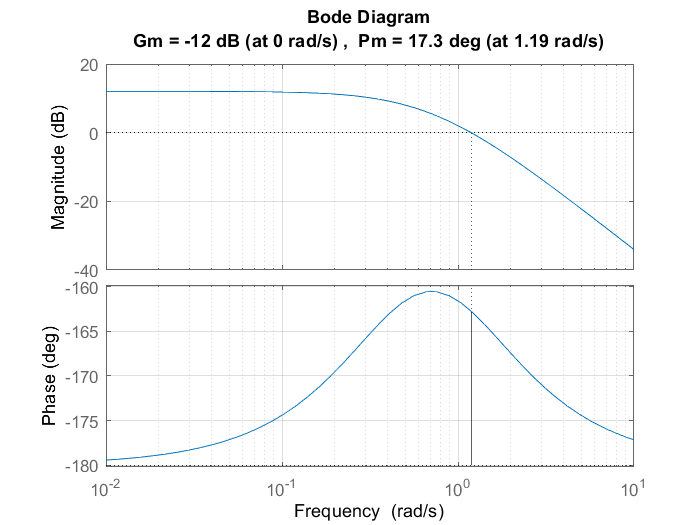


s=tf('s');
G0=k/(s+1)/(s-0.5);
margin(G0);
grid on;

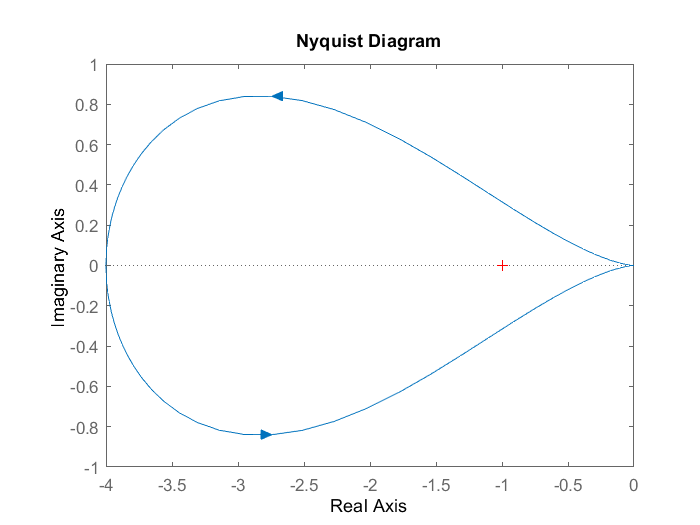


figure
P=nyquistplot(G0);

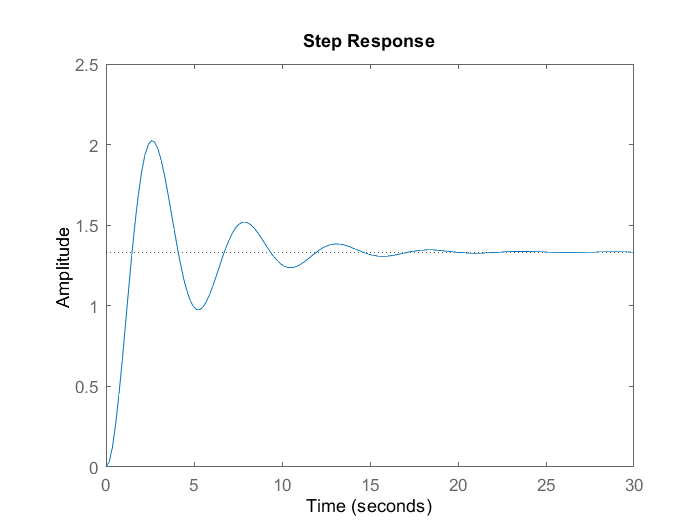

% xlim([-200,100])
% ylim([-100 1000])
setoptions(P,'ShowFullContour','on')
step(feedback(G0,1));